# Lab 11

## Read the image

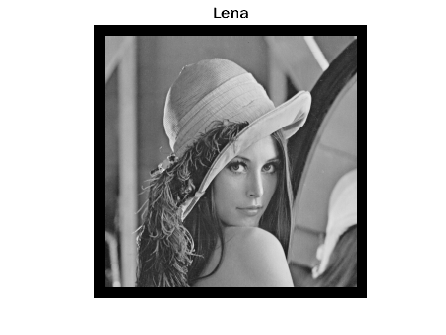

img_lena = imread('lena.png');
imshow(img_lena)
title("Lena")

## 1a) Minimum RMSE 

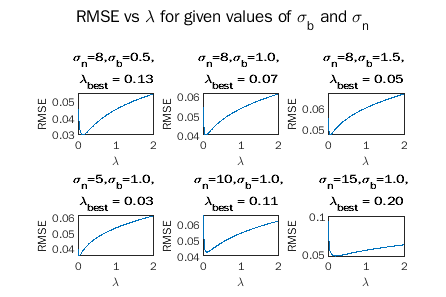

% All combinations of sigma_n and sigma_b
sigma_n_vals = [8 8 8 5 10 15];
sigma_b_vals = [0.5 1 1.5 1 1 1];
n_combs = length(sigma_n_vals);

figure1=figure('Position', [0, 0, 1500, 1000]);
% For each configuration, we blur the original image with sigma_b and 
% sigma_n and then iterate through values of lambda from 0.01 to 2.0 in
% steps of 0.01. The "best_lam" is the value of lambda which gives the
% lowest RMSE between the deblurred and original image. 
for i = 1:n_combs
    sig_n = sigma_n_vals(i);
    sig_b = sigma_b_vals(i);
    blur_ker = get_kernel(sig_b);
    [best_lam,rmse_vals,deblurred_img] = best_l2_lambda(img_lena, blur_ker, sig_n);
    subplot(2,3,i)
    x = 0.01:0.01:2.0;
    plot(x, rmse_vals)
    xlabel(sprintf('\\lambda'))
    ylabel('RMSE')
    title(sprintf('\\sigma_n=%d,\\sigma_b=%.1f, \n\\lambda_{best} = %.2f', sig_n,sig_b,best_lam))
end
sgtitle(sprintf('RMSE vs \\lambda for given values of \\sigma_b and \\sigma_n'))
saveas(figure1, "plot_q1a.png", 'png')

The values of lambda with least RMSE are shown for each configuration. We see that for each configuration, there exists atleast one local minima among the iterated values. 

When sigma_n is constant, lambda decreases with increase in sigma_b. On the other hand, when sigma_b is kept constant, lambda increases with increase in sigma_n. The same observation is also seen in the visual-best images.

## 1b) Visual best deblurred images

The values of lambda which gave the visual-best image for each configuration were computed by trial and error. For the best values of lambda, we show the deblurred images for each configuration.

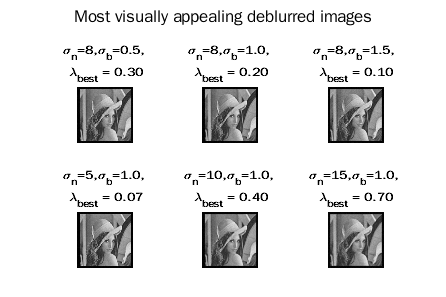

best_visual_lambdas_l2 = [0.3, 0.2, 0.1, 0.07, 0.4, 0.7];
figure2=figure('Position', [0, 0, 1500, 1000]);
for ind = 1:6

    blur_ker = get_kernel(sigma_b_vals(ind));
    f_hat = get_deblurred_img(img_lena, blur_ker, sigma_n_vals(ind), best_visual_lambdas_l2(ind), "L2");
    subplot(2,3,ind)
    imshow(f_hat)
    title(sprintf('\\sigma_n=%d,\\sigma_b=%.1f, \n\\lambda_{best} = %.2f', sigma_n_vals(ind),sigma_b_vals(ind),best_visual_lambdas_l2(ind)))
end
sgtitle(sprintf('Most visually appealing deblurred images'))
saveas(figure2, "plot_q1b.png", 'png')

We can clearly see that as the noise increases, the deblurring is less effective. This is expected. We also notice, when we find the best value of lambda, that increasing value of lambda reduces the noise but leads to a more blurry image. Consequently, decreasing lambda leads to sharper images but with more noise.

Comparing 1a and 1b, the best value of lambda is different when RMSE is used as a metric vs when the best looking image is chosen. This is probably because sharpness and blurriness of the image as perceived by our eye is not exactly captured by the RMSE metric.

## 2) Comparing L1 and L2 regularization

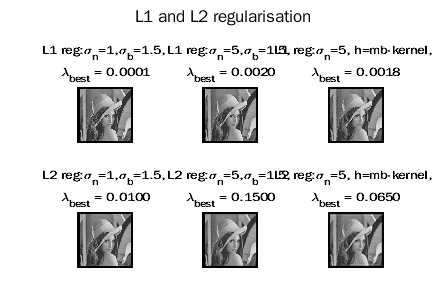

ker3 = im2double(imread("mb-kernel.png"));
ker3 = ker3/sum(ker3(:));
% adding blur kernels and sigma_n for all 3 cases to lists
blur_kernels = {get_kernel(1.5), get_kernel(1.5), ker3};
sigma_n_values = {1, 5, 5};
% The visual-best values of lambda were computed by trial and error 
% for all 3 cases and were found to take the values below.
lambda_l1_best = [0.0001 0.002 0.0018];
lambda_l2_best = [0.01 0.15 0.065];

figure3=figure('Position', [0, 0, 1500, 1000]);

for j = 1:length(sigma_n_values)
    subplot(2,3,j)
    % L1 Regularisation
    f_hat = get_deblurred_img(img_lena, blur_kernels{j}, sigma_n_values{j}, lambda_l1_best(j), "L1");
    imshow(f_hat)
    if j==3
        % Motion Blur case
        title(sprintf('L1 reg:\\sigma_n=%d, h=mb-kernel, \n\\lambda_{best} = %.4f', sigma_n_values{j},lambda_l1_best(j)))
    else
        title(sprintf('L1 reg:\\sigma_n=%d,\\sigma_b=1.5, \n\\lambda_{best} = %.4f', sigma_n_values{j},lambda_l1_best(j)))
    end

    subplot(2,3,j+3)
    % L2 Regularisation
    f_hat = get_deblurred_img(img_lena, blur_kernels{j}, sigma_n_values{j}, lambda_l2_best(j), "L2");
    imshow(f_hat)
    if j==3
        % Motion Blur case
        title(sprintf('L2 reg:\\sigma_n=%d, h=mb-kernel, \n\\lambda_{best} = %.4f', sigma_n_values{j},lambda_l2_best(j)))
    else
        title(sprintf('L2 reg:\\sigma_n=%d,\\sigma_b=1.5, \n\\lambda_{best} = %.4f', sigma_n_values{j},lambda_l2_best(j)))
    end
end
sgtitle(sprintf('L1 and L2 regularisation'))
saveas(figure3, "plot_q2.png", 'png')

The lambda which gave the most visually appealing deblurred image was chosen for all 6 configurations. We see that the values of lambda for L1 regularization is much lower than that of L2 regularization. 

We also notice see that images produced by L1 regularisation are much sharper than L2 regularisation. L1 regularisation is also able to almost fully deblur the motion blur in the last case while the same is not applicable with L2 reg. However, the time taken for L1 regularisation is much larger than that of L2 regualrisation since L2 reg is efficiently implemented in the frequency domain. Therefore, there is a trade-off between performance and time consumption.

## Functions

function blur_img = blur(img, kernel, sigma_n) % blur function 
% Returns the blurred image given a clear image and the kernel additive noise variance to be
% used for blurring.
    noisy_img = conv2(img, kernel, 'same');
    blur_img = imnoise(noisy_img, 'gaussian',0, (sigma_n/255)^2);
end

% Function to compute the gaussian kernel given the value of sigma
function kernel = get_kernel(sigma)
    % n is the kernel size
    n = ceil(6*sigma + 1);
    % n=1 is a trivial case
    if n==1
        kernel = ones(1,1);
    else
        % Make n odd
        if mod(n,2)==0
            n=n+1;
        end

        % Compute all the values of the gaussian kernel
        d = ceil(n/2);
        [x, y] = meshgrid(1:n, 1:n);
        exponent = -((x-d).^2 + (y-d).^2)/(2*sigma^2);
        kernel = exp(exponent);
        kernel = kernel/sum(kernel(:));
    end
end

% For L2 regularization, iterate through lambda from 0.1 to 2.0 and return
% the lambda with the lowest RMSE
function [best_lambda, rmse_vals, deblurred_img] = best_l2_lambda(img, blur_kernel, sigma_n)
    % Convert image to type double
    img = im2double(img);
    [l, w] = size(img);
    % Compute H, Qx, Qy, and G as given in the question
    H = psf2otf(blur_kernel, [l w]);

    qx = [1 -1];
    qy = [1; -1];
    Qx = psf2otf(qx, [l w]);
    Qy = psf2otf(qy, [l w]);

    blurred_image = blur(img, blur_kernel, sigma_n);
    G = fft2(blurred_image);
    lambdas = 0.01:0.01:2.0;
    rmse_vals = zeros(size(lambdas));
    deblurred_img = zeros(l, w);
    rmse_min = Inf;
    best_lambda = 0.01;
    for i = 1:size(rmse_vals,2)
        lamb = lambdas(i);
        % Compute f_hat from the expression given for L2 reg
        f_hat_temp = (conj(H)./(conj(H).*H + lamb*(conj(Qx).*Qx + conj(Qy).*Qy))).*G;
        f_hat = ifft2(f_hat_temp);

        assert(isequal(size(f_hat),size(img)))
        
        % Find lambda with min RMSE
        rmse_i = sqrt(mean((img(:)-f_hat(:)).^2));
        rmse_vals(i) = rmse_i;
        if rmse_i < rmse_min
            rmse_min = rmse_i;
            best_lambda = lamb;
            deblurred_img = f_hat;
        end

    end
    
end

% Function to compute the deblurred image given regularisation type and
% lambda
function deblur_img = get_deblurred_img(img, blur_kernel, sigma_n, lamb, reg)
    img = im2double(img);
    [l, w] = size(img);
    % Compute blurred image from the original image and the blurring
    % parameters
    blurred_image = blur(img, blur_kernel, sigma_n);

    % L1 reg: Use the given admmfft function
    if reg=="L1"
        deblur_img = admmfft(blurred_image, blur_kernel, lamb, 1);
    % L2 reg: Evaluate the deblurred image in the frequency domain as given
    % in the question.
    else
        H = psf2otf(blur_kernel, [l w]);
        qx = [1 -1];
        qy = [1; -1];
        Qx = psf2otf(qx, [l w]);
        Qy = psf2otf(qy, [l w]);
        
        G = fft2(blurred_image);
        % Compute f_hat(deblur_img) from the expression given for L2 reg
        f_hat_temp = (conj(H)./(conj(H).*H + lamb*(conj(Qx).*Qx + conj(Qy).*Qy))).*G;
        deblur_img = ifft2(f_hat_temp);
    end
    assert(isequal(size(deblur_img),size(img)))
    
end